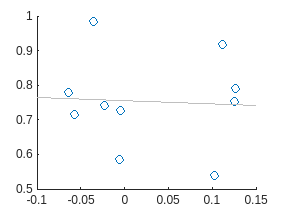

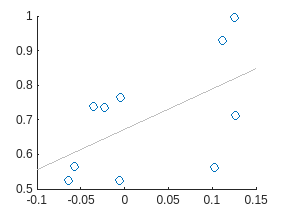

BD


                       Mean      Variance
                     ________    ________

    spearman corr    0.090909    0.46667 
    p                 0.37749    0.14866 



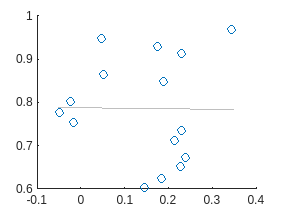

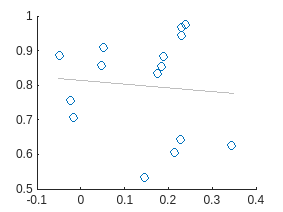

SCA


                      Mean      Variance
                     _______    ________

    spearman corr     -0.025    0.13929 
    p                0.48257    0.31559 



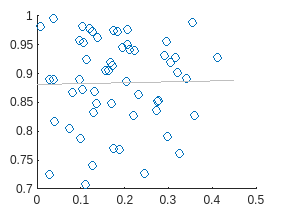

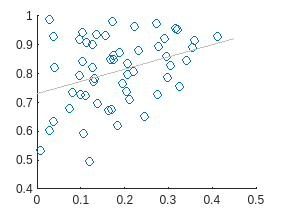

SCZ


                        Mean       Variance
                     __________    ________

    spearman corr    -0.0039683     0.28925
    p                   0.49614    0.074569



% Consider the confound of age-onset when analyzing brain t-map correlations.
% The script calculates the mean and variance ratios of age-onset between sites
% and uses these as confounds in analyzing correlation matrices for various diagnoses.

clear all
close all

% Set parameters for analysis
iCOMBAT = 1;            % Flag for using COMBAT harmonization
smoothKernel = 6;       % Smoothing kernel size
iter = 5000;            % Number of iterations for Mantel test
type = 'spearman';      % Type of correlation to use ('spearman')
diagnosisString = {'BD', 'SCA', 'SCZ', 'ASD', 'MDD', 'AD'}; % List of disorders to analyze

nDiag = length(diagnosisString); % Number of disorders

% Define data directory based on COMBAT flag
if iCOMBAT == 1
    address = ['derivatives/s', num2str(smoothKernel), 'COMBAT/'];
else
    address = ['derivatives/s', num2str(smoothKernel), '/'];
end

% Load metadata
metadata = readtable(['/projects/kg98/trangc/VBM/data/metadataVBM_extended.csv']);

% Load pre-computed correlation matrices and site lists
load(['output/corr_tmap_combat', num2str(iCOMBAT), '_smooth', num2str(smoothKernel), '.mat'], ...
     'cor1', 'cor2', 'siteList');

% Iterate over each diagnosis
for iDiag = 1:nDiag
    % Compute mean and variance ratios of age-onset and perform Mantel test
    [varTable{iDiag}, nSite{iDiag}] = cor_var_ageonset(metadata, diagnosisString(iDiag), cor1{iDiag}, cor2{iDiag}, siteList{iDiag},iter, type);

    % Display results if the output table is not empty
    if size(varTable{iDiag}, 1) ~= 0
        disp(char(diagnosisString(iDiag))); % Print the current diagnosis name
        disp(varTable{iDiag});             % Display the results table
        disp(' ');
        disp(' ');
    end
end


% Turn off warnings for 'last' to avoid repetitive warning messages
warning('off', 'last');

Error using warning
The last warning issued had an empty warning identifier, or no warnings have yet been issued.


% Save results to a .mat file
save('output/confound_ageonset.mat', 'varTable', 'nSite');
